## 1-RoboRobot Parameters and Schemet Parameters and Scheme

 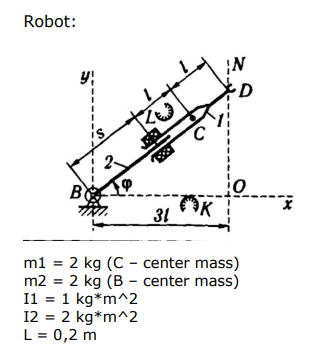

I will change our refrences :

m1 = 2 kg (B - center mass)

m2 = 2 kg (C - center mass)

I1 = 2 kg*m^2

I2 = 1 kg*m^2

L = 0.2 m

clear
close all
syms q1 q2 dq1 dq2 ddq1 ddq2 l d1 d2 m1 m2 I1 I2 g real

## 2-forward kinematics


$$FK = Rz(q1) * Tx(q2) * Tx(2*l)$$


FK= Rz(q1) * Tx(q2) * Tx(2*l)

$$FK = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 2\,l\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 2\,l\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## 3- joints & center of mass locations

O0 = [0 0 0]'

O0 =      0
     0
     0


O1 = [0 0 0]'

O1 =      0
     0
     0


O2 = [(q2+2*l)*cos(q1) (q2+2*l)*sin(q1) 0]'

$$O2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(2\,l+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(2\,l+q_{2}\right)\\ 0 \end{array}\right)$$

Oc1 = [0 0 0]'

Oc1 =      0
     0
     0


Oc2 = [(q2+l)*cos(q1) (q2+l)*sin(q1)  0 ]'

$$Oc2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(l+q_{2}\right)\\ 0 \end{array}\right)$$

## 4- get the Z

Z0 = [0 0 1]'

Z0 =      0
     0
     1


Z1 = [cos(q1) sin(q1) 0]'

$$Z1 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

## 5- Jv for joints

% Jv1
Zer = [0 0 0]';
Jv1 = [cross(Z0,(Oc1-O0)), Zer]

Jv1 =      0     0
     0     0
     0     0



% Jv2
Jv2 = [cross(Z0,(Oc2-O0)), Z1]

$$Jv2 = \left(\begin{array}{cc} -\sin\left(q_{1}\right)\,\left(l+q_{2}\right) & \cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\left(l+q_{2}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

## 6- Jw for joints

% Jw1
Jw1 = [Z0, Zer]

Jw1 =      0     0
     0     0
     1     0



% Jw2
Jw2 = [Z0 ,Zer]

Jw2 =      0     0
     0     0
     1     0


R1 = [ cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1]

$$R1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = [ cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1]

$$R2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

## 7- Kinetic Energy Calculations


q = [q1;q2];
D1 = (m1*Jv1')*Jv1 + Jw1'*R1*I1*R1'*Jw1

$$D1 = \left(\begin{array}{cc} I_{1} & 0\\ 0 & 0 \end{array}\right)$$

D2 = (m2*Jv2')*Jv2 + Jw2'*R2*I2*R2'*Jw2

$$D2 = \left(\begin{array}{cc} I_{2}+m_{2}\,{\cos\left(q_{1}\right)}^{2}\,{\left(l+q_{2}\right)}^{2}+m_{2}\,{\sin\left(q_{1}\right)}^{2}\,{\left(l+q_{2}\right)}^{2} & 0\\ 0 & m_{2}\,{\cos\left(q_{1}\right)}^{2}+m_{2}\,{\sin\left(q_{1}\right)}^{2} \end{array}\right)$$


D=D1+D2;
D=simplify(D)

$$D = \left(\begin{array}{cc} m_{2}\,l^{2}+2\,m_{2}\,l\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

## 8- Potential Energy Calculations


P1 = 0;
P2 = m2*g*(l+q2)*sin(q1);
P = P1+P2;
G1 = diff(P, q1)

$$G1 = g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)$$

G2 = diff(P, q2)

$$G2 = g\,m_{2}\,\sin\left(q_{1}\right)$$


G = [G1; G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

## 9- Coriolis Force Calculation


dq = [dq1; dq2];
ddq = [ddq1; ddq2];
C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} {\mathrm{dq}}_{2}\,m_{2}\,\left(l+q_{2}\right) & {\mathrm{dq}}_{1}\,m_{2}\,\left(l+q_{2}\right)\\ -{\mathrm{dq}}_{1}\,m_{2}\,\left(l+q_{2}\right) & 0 \end{array}\right)$$

## 10- Equation of motion

tor = D*ddq+C*dq+G

$$tor = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(m_{2}\,l^{2}+2\,m_{2}\,l\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)+g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\left(l+q_{2}\right)\\ -m_{2}\,\left(l+q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,m_{2}+g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

D(q1,q2) = subs(D,{m1, m2, I1, I2, l},{2 2 2 1 0.2})

$$D(q1, q2) = \left(\begin{array}{cc} 2\,{q_{2}}^{2}+\frac{4\,q_{2}}{5}+\frac{77}{25} & 0\\ 0 & 2 \end{array}\right)$$

C(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2, I1, I2, l},{2 2 2 1 0.2})

$$C(q1, q2, dq1, dq2) = \left(\begin{array}{c} 4\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(q_{2}+\frac{1}{5}\right)\\ -2\,{{\mathrm{dq}}_{1}}^{2}\,\left(q_{2}+\frac{1}{5}\right) \end{array}\right)$$

G(q1,q2) = subs(G ,{m1, m2, I1, I2, l, g},{2 2 2 1 0.2 9.81})

$$G(q1, q2) = \left(\begin{array}{c} \frac{981\,\cos\left(q_{1}\right)\,\left(q_{2}+\frac{1}{5}\right)}{50}\\ \frac{981\,\sin\left(q_{1}\right)}{50} \end{array}\right)$$

## 11-Initial Positions, Velocities, Torques & Forces

q1_0 = 0;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;



dt=0.01;
U = [300;100];
n=300;
q1p= zeros(1,n);
q2p= zeros(1,n);
dq1p= zeros(1,n);
dq2p= zeros(1,n);
ddq1p= zeros(1,n);
ddq2p= zeros(1,n);

for i = 1:n

 q1p(1,i)=q1_0;
 q2p(1,i)=q2_0;
 dq1p(1,i)=dq1_0;
 dq2p(1,i)=dq2_0;
 ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));

 dq1_0=dq1p(1,i) + double(ddq(1)*dt);
 dq2_0=dq2p(1,i) + double(ddq(2)*dt);

 q1_0 = q1p(1,i) + dq1_0*dt;
 q2_0 = q2p(1,i) + dq2_0*dt;
 
 ddq1p(1,i)= double(ddq(1));
 ddq2p(1,i)=double(ddq(2));


end
t = 0:0.1:(0.1*(n-1));


## 12- Position Plot

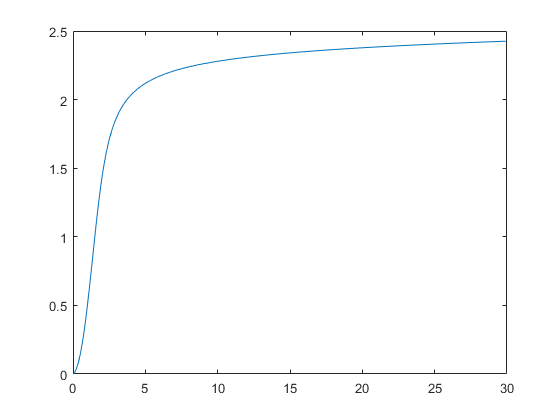

plot(t,q1p)

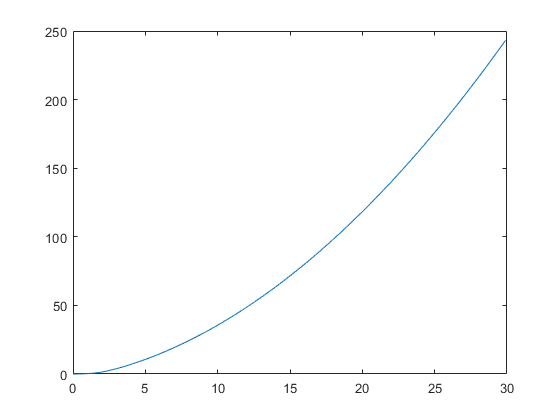

plot(t,q2p)

## 13- Velocity Plot

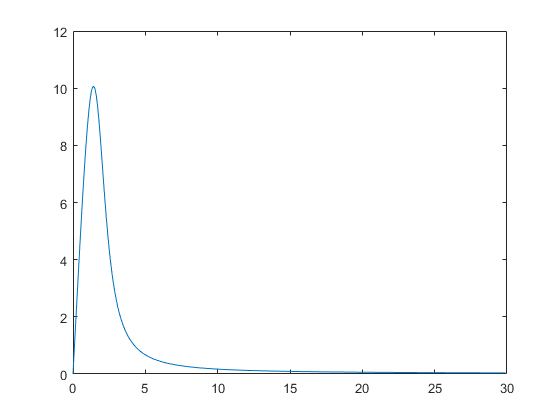

plot(t,dq1p)

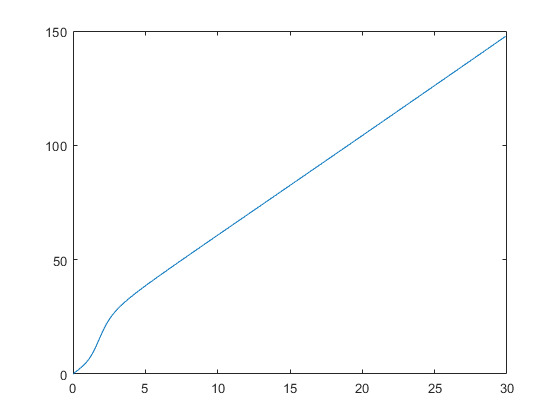

plot(t,dq2p)

## 14- Position Plot

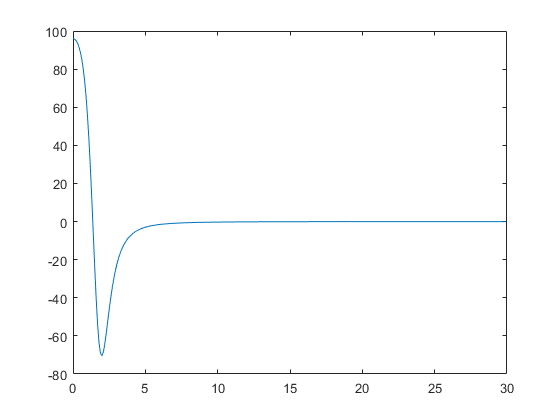

plot(t,ddq1p)

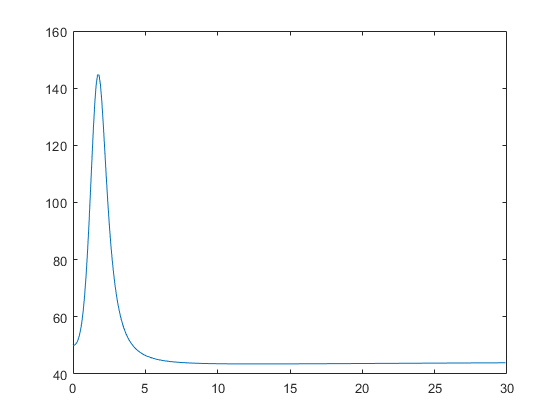

plot(t,ddq2p)

## 15- Torque & Forces Plot

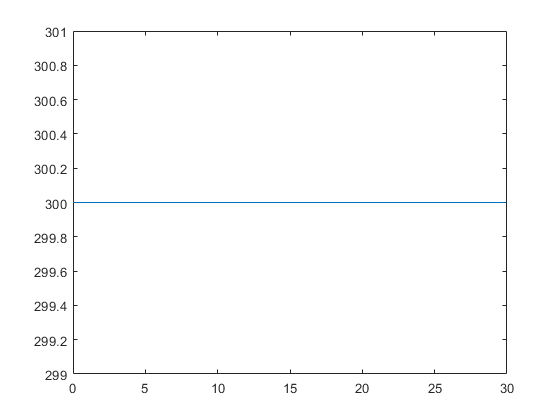

torque=U(1)*ones(1,n);
force=U(2)*ones(1,n);

plot(t,torque)

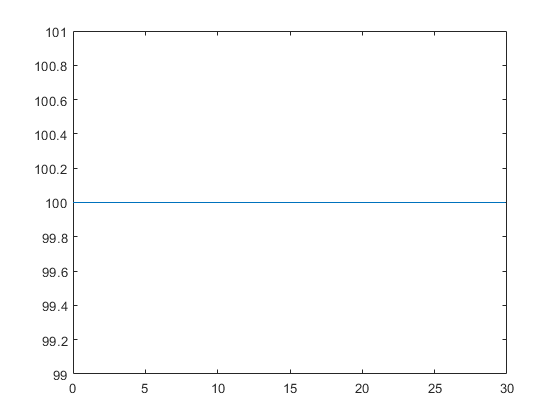

plot(t,force)